# Perception Basic Process Live Notebook

## Getting Add-Ons

Please make sure you have the following toolboxes installed before you proceed:

- [**Computer Vision Toolbox** ](https://www.mathworks.com/add-ons/VP/?s_tid=srchtitle)

- [**Statistics and Machine Learning Toolbox**](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'ST', 'focused', 'pca');)**.**

- **Deep Learning Toolbox**

- [**Computer Vision Toolbox Model for** **YOLO** **v4 Object Detection**](https://www.mathworks.com/add-ons/YOLOV4/?s_tid=srchtitle)

## Getting the Files

There will be two steps to download necessary files: (1) Regular files via GIT/Canvas as usual and Large Neural Net Yolo files downloaded from Canvas.

### (1) GIT Files

Fetch and Merge the latest files from GIT.

You should see a folder structure as the one below. Make **tutorials/vision **the top folder in your matlab path:

pcdownsample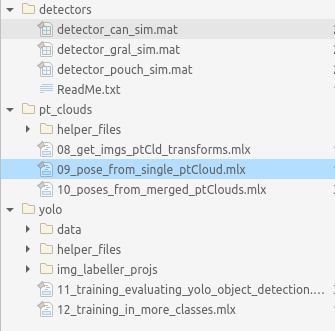

### (2) Detector Files

Download detector files from Canvas inside the *files/05_ros_code/vision/yolo/detectors* and place the detector file in the **ros_matlab/tutorials/vision/detectors **folder. 

Each detector is ~230MB in size.

### *Add to Matlab Path

Add **ros_matlab/tutorials/vision/detectors** in a new folder with sub-folders inside of it. 

Please add it to your Matlab path.

## Overview

The general process: 

- Requires a RGB image and a point cloud taken from the same position

- Uses a pre-trained YOLO network to identify objects from the raw RGB image

- Pre-process the point cloud (downsample and extract the non-plane)

- Uses the YOLO output bounding boxes to extract objects from the point cloud

- Estimates the objects pose

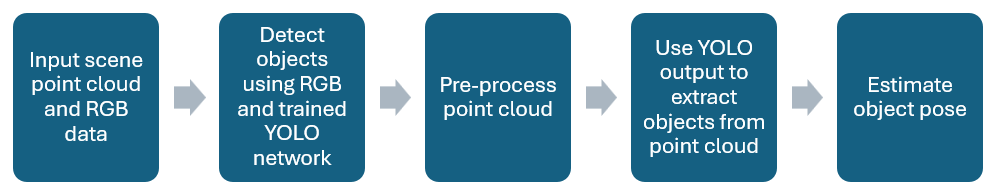

## Key Functions

### Yolo

- [detect()](https://www.mathworks.com/help/vision/ref/yolov2objectdetector.detect.html)

- [insertObjectAnnotation()](https://www.mathworks.com/help/vision/ref/insertobjectannotation.html)

### Point Clouds

- [pcshow()](https://www.mathworks.com/help/vision/ref/pcshow.html?searchHighlight=pcshow&s_tid=srchtitle_support_results_1_pcshow)

- [pcfitPlane()](https://www.mathworks.com/help/vision/ref/pcfitplane.html)

- [select()](https://www.mathworks.com/help/vision/ref/pointcloud.select.html)

- findObjectPoses -- locally defined.

## Connect to the Simulation

We will open up the UR simulation in gazebo.

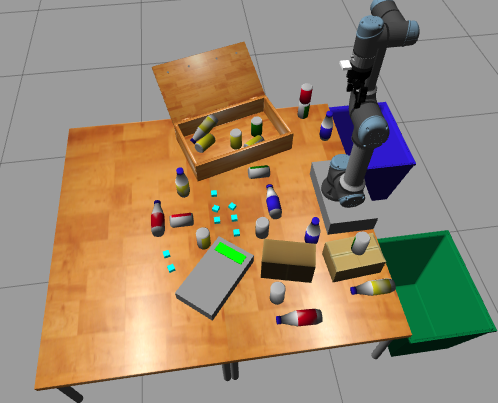

### Run your Virtual Machine

To this end, you will need to run your virtual machine and start the armgazebo container. 

### Run your Container

Remember to call run.bash from inside src/arm_gazebo/docker:

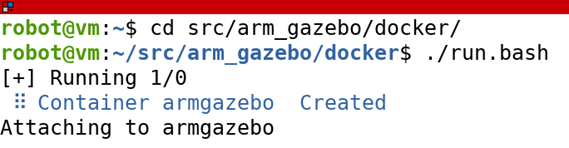

Also retrieve your hostname via command: hostname -I

### Connect MATLAB to Gazebo using the ROS Toolbox

Note: for connections inside Lipscomb's network make sure you have already updated your hosts files by setting the IP address above followed by VM.

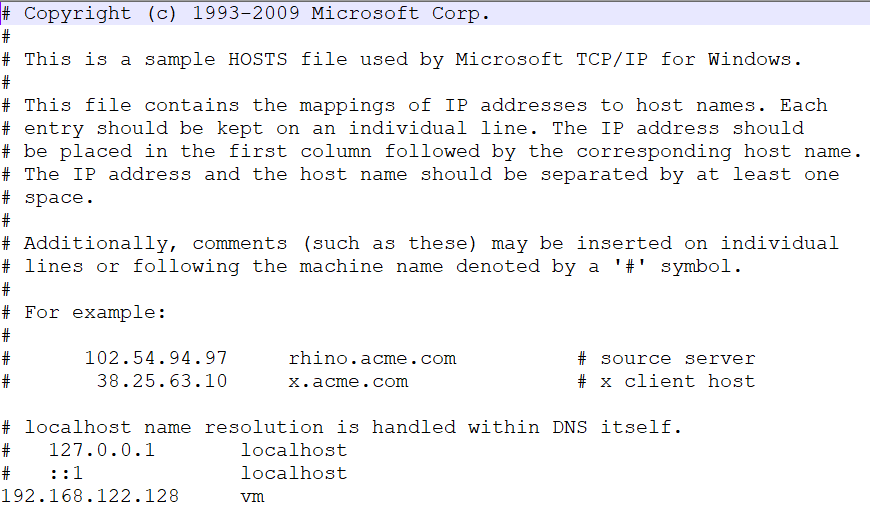

Once, you have done that, you can simply call rosinit with the IP address of your virtual machine:

masterHostIP = "10.52.53.249";
nodeHostIP = "10.52.50.146";
rosinit(masterHostIP, 11311, "NodeHost",nodeHostIP);

## Read sample point cloud and sample RGB data 

The point cloud and the raw image collected need to be taken from the same position.

Load the example `rgbImage` and example `ptCloud` found in the pt_clouds/helper_files folder 

load("./tutorials/vision/pt_clouds/helper_files/example_ptCloud_and_image.mat");

The image is a top-down view of objects on a table. There are cans, bottles, and pouches (the cyan-colored squares) in the image. It looks like the picture below.

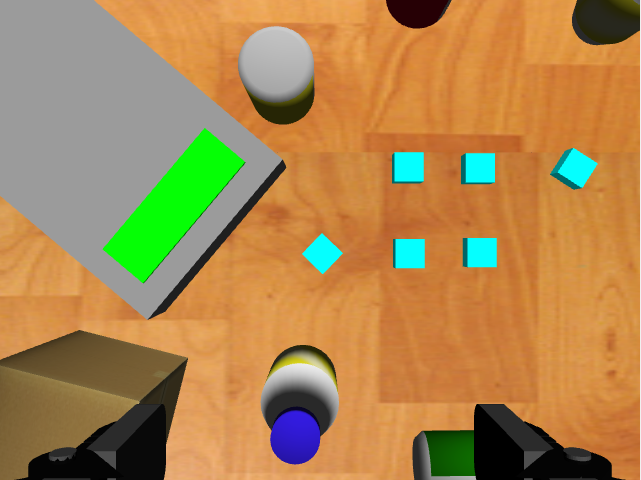

Display the image in your own system:

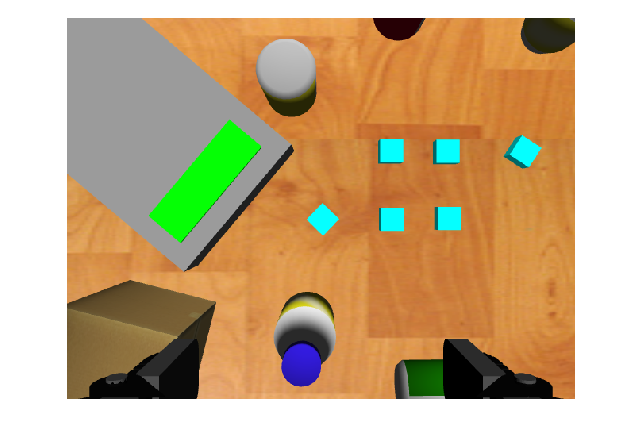

figure, imshow(rgbImage)

## Detect objects using trained YOLO network

In order to identify objects, we need to leverage a trained YOLO network to the image. 

1. Load pre-trained network (it will take several seconds):

mainPath = "/data/docs/school/teaching/eece4523-robotics/code/ros_matlab"; % Adjust for your computer.
detectorPath = "./tutorials/vision/detectors/detector_gral_sim.mat";
pretrained = load( fullfile(mainPath,detectorPath) ); 

2. Extract the object detector:

trainedYoloNet = pretrained.detector; % specifically accessing the detector

3. Compute bounding boxes using loaded detector via the function **detect** which takes:

- a detector object

- an image, and a

- threshold

[bboxes,scores,labels] = detect(trainedYoloNet,rgbImage,Threshold=0.997);
numObjects = size(bboxes,1);

`The output yields 3 variables:`

- `bboxes:` P-by-4 array defining P bounding boxes. Each row of `bboxes` contains a four-element vector, [x, y, width, height]. This vector specifies the upper-left corner and size of a bounding box in pixels. 

- `scores:` confidence scores for each bounding box (P-by-1)

- `labels:` labels assigned to the bounding boxes (P-by-1)

#### Threshold

Specifically notice the `threshold` parameter input of the `detect` function. This `threshold` outputs classifications for objects whose `scores`** are higher than the specified **`threshold`.

The threshold needs to be determined such that only a single box is output (or alternatively choose the box with the highest confidence value).

### **Visualize bounding boxes on raw RGB data**

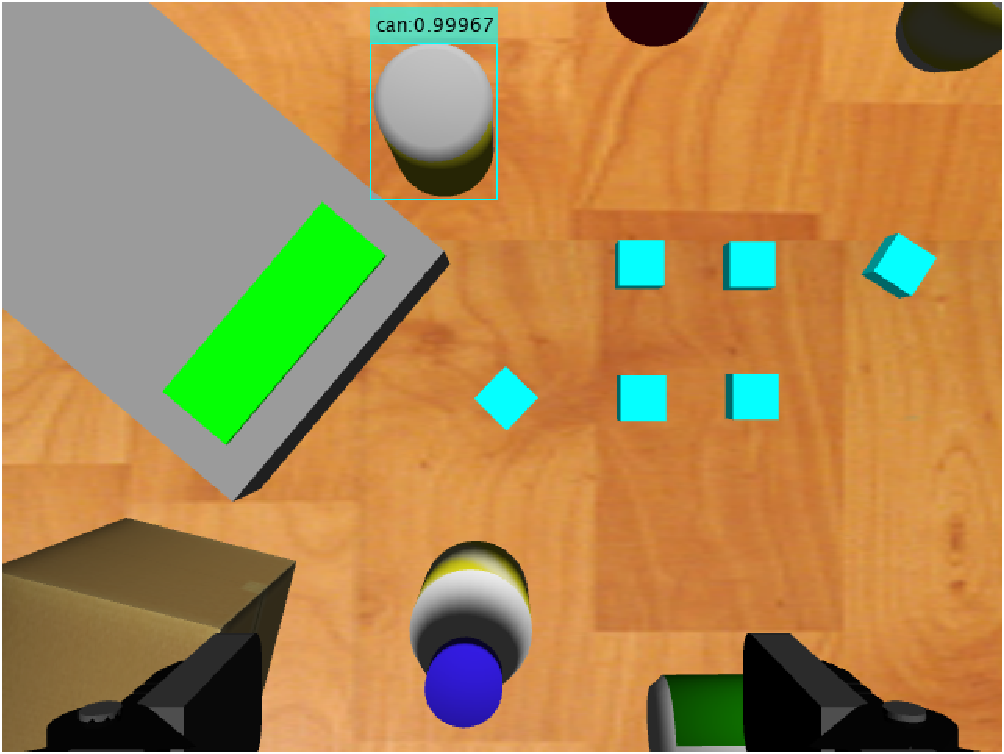

Visualize the computed bounding box with the raw RGB input data on your own system via the **insertObjectAnnotation** method. 

The result should look similar to the picture above.

annotatedImage = insertObjectAnnotation(im2uint8(rgbImage), ...
                                        'Rectangle',...
                                        bboxes,...
                                        string(labels)+":"+string(scores),...
                                        'Color','cyan');
figure, imshow(annotatedImage);

## Remove table plane from the point cloud

Now that we have the bounding box, we want to extract the center of mass of the target object. To do so, we will have to remove points that live on the plane. 

Our current point cloud looks like the picture below.

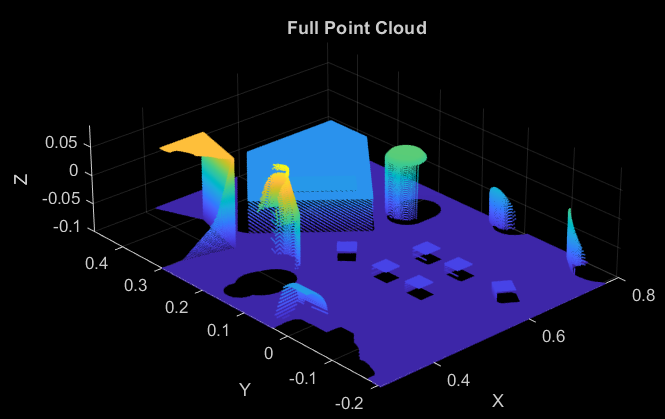

Plot the raw point cloud data

figure, pcshow(ptCloud,'ViewPlane','XY','VerticalAxisDir','Down'); 
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Raw Point Cloud");

### Identifying plane and non-plane points

Remove the plane from the raw point cloud data for further computation. (In our case the "plane" is the table the objects are on. We want to isolate the objects from the table.)

To do so, first identify the point clouds associated with a plane defined by the z-vec [ 0 0 1]. 

We will use [**model = pcfitplane(ptCloudIn,maxDistance,referenceVector,maxAngularDistance)**](https://www.mathworks.com/help/releases/R2025a/vision/ref/pcfitplane.html?searchPort=60359) which will produce a plane equation 

    ax + by + cz + d = 0.

Given such plane, each point in the point cloud can will either be associated with the plane or not. 

The points indeces will be stored in two variables:

- **planeIdx** (double)

- **nonPlaneIdx **(double)

planeThickness = .001;       % meters
normalVector = [0,0,1];      % z-axis  
maxPlaneTilt = 5;            % Degrees

% Compute model of the plane (param associated with 4 coeffs ax + by + cz + d = 0)
[param, planeIdx, nonPlaneIdx] = pcfitplane(ptCloud, ...
                                            planeThickness, ...
                                            normalVector, ...
                                            maxPlaneTilt);

Now we can extract the desired points in the point cloud via [selection = select(pts,plane)](https://www.mathworks.com/help/releases/R2025a/ros/ref/select.html?overload=select+false&searchPort=60359) and pass the vector of indeces. Below we separate plane and nonPlane points:

% Assign to variables, which points belong to the plane and which do not
plane = select(ptCloud, planeIdx);
nonPlane = select(ptCloud, nonPlaneIdx);

Note that plane and nonPlane are still pointCloud objects, but only contain values for the desired indeces:

class(plane)

ans = 'pointCloud'

plane

plane =   pointCloud with properties:

     Location: [193656×3 single]
        Count: 193656
      XLimits: [-0.3388 0.3388]
      YLimits: [-0.2539 0.2540]
      ZLimits: [0.5868 0.5878]
        Color: []
       Normal: []
    Intensity: []


### Visualizing the Plane

Plane and nonPlane points can be visualized via pcShow:

% Show the plane
figure, pcshow(plane,'ViewPlane','XY');axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Extracted Plane from ptCloud");

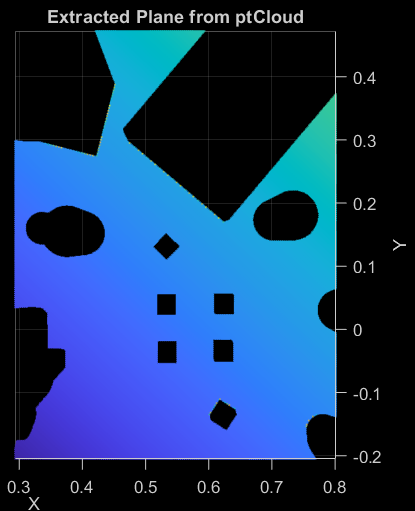

### Visualizing the Objects

The more interesting part is diplaying the objects (i.e. the nonPlane). 

% show items
figure,pcshow(nonPlane,'ViewPlane','XY');axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("nonPlane of ptCloud");

Note that you can manipulate the view to see the 3D scene:

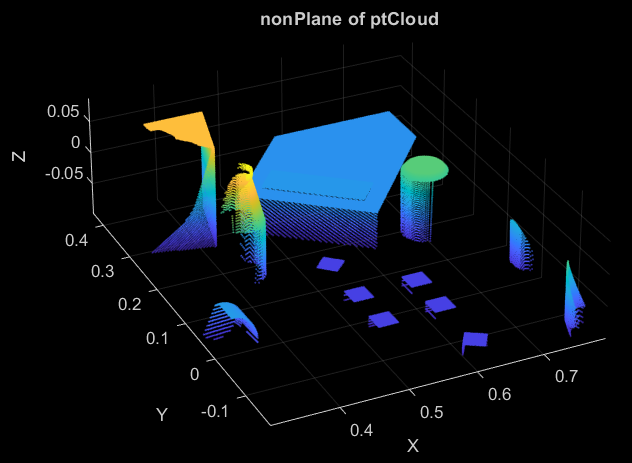

#### **nonPlane Mask**

Masks are a simple yet useful representation that will tell us which indices pertain to some objective. 

The nonPlane mask for example, will hold values of 1 for index entries that correspond to objects. 

It is extracted as follows:

% Extract width and height from point cloud
[m,n,~] = size(rgbImage);

% Create an empty matrix with the same dimensions
nonPlaneMask = zeros(m,n);      

% Flatten (convert) the matrix into a column vector
nonPlaneMask = nonPlaneMask(:); 

% Set a value of 1 for all indeces in which there is an object. 
% Matlab allows us to pass multiple indeces at the same time as follows:
nonPlaneMask(nonPlaneIdx)= 1;

## Estimate object poses (findObjectPoses) wrt to the Camera Link

This section estimates the object poses wrt to the camera (not the robot base -- we will learn that in the next notebook) using the bounding box from yolo and the pre-processed point cloud data. 

- If you have two bounding boxes for examples, you will produce two positions/orientations. 

- In practice a single box is desired per attempt. More on this later.

The `findObjectPoses()` function computes the positions (`xyz`) and orientations (`theta`) of objects detected by a YOLO neural network by:

- **Segmentation:**It uses YOLO-generated bounding boxes and masks to isolate each object within the original point cloud.

                 

- **Point Cloud Refinement:**Each object's points are further downsampled via [pcdownsample](https://www.mathworks.com/help/releases/R2025a/vision/ref/pcdownsample.html?searchPort=50829) and refined to remove noise and isolate the largest point cluster via [pcsegdist](https://www.mathworks.com/help/releases/R2025a/vision/ref/pcsegdist.html?searchPort=50829), assuming this represents the object of interest.

            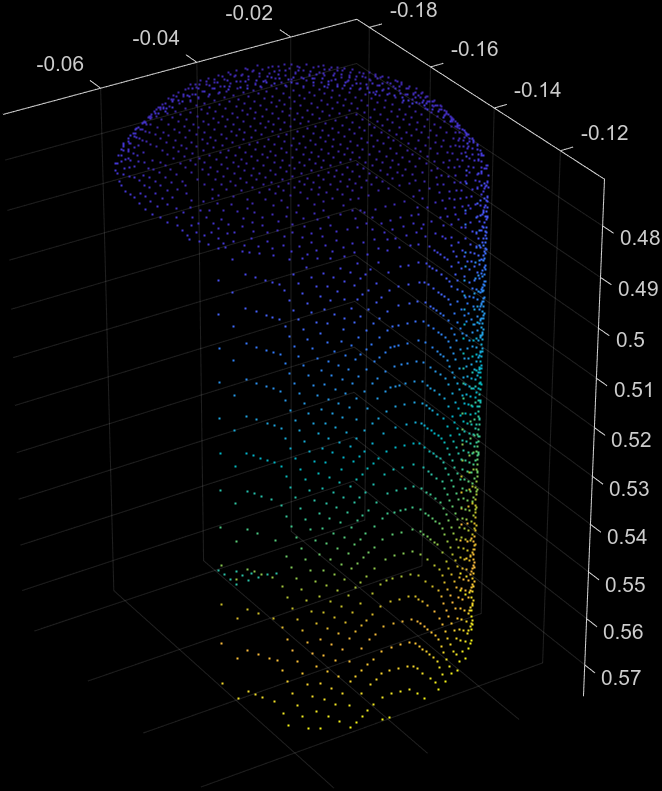

- **Center of Mass (Centroid) Calculation:**It calculates the centroid (average position) of the points representing each object - it can be done with respect to the CoM of the object itself or the center of the bounding box.

- **Principal Component Analysis (PCA):**It applies PCA to determine the directions of maximum and minimum variance in the spatial distribution of the points. These directions define the principal axes: the axis with the greatest variability typically aligns with the object's length (major axis). Axes with progressively less variability define width and height.

- **Orientation Determination:**The major axis (direction of greatest variability from PCA) is used to determine the orientation angle (`theta`) relative to a fixed reference axis (typically the +x-axis).

- **Visualization:**Finally, the function visualizes each segmented object's point cloud along with its principal axes, making the results intuitive.

At a more granular level we are doing the following for each object:

- Generate object mask

- Extract and Downsample Points

- Segment Points into clusters

- Perform PCA Analysis

- Store PCA Results

- Calculate Object Orientation

- Determine Object Position

gridDownsample = 0.002;
[xyz,theta,ptCloud_vec,scene_pca_vec] = findObjectPoses(ptCloud, rgbImage, bboxes, gridDownsample, nonPlaneMask);

### Visualize each object 

Create visualizations of each segmented object's point cloud and its principal axes.

Question:

- Do the centroids in the visualizations below look correct? Why or why not?

- How could you further improve them?

figure;

% For however many number of objects there are:
for idx = 1: numObjects

    % Retrieve PCA vectors (principal axes) for visualization
    U = scene_pca_vec{idx}.UVW(:,1);
    V = scene_pca_vec{idx}.UVW(:,2);
    W = scene_pca_vec{idx}.UVW(:,3);

    % Centroid of the current object
    center = scene_pca_vec{idx}.centroid;

    % Create subplot for current object
    nexttile;

    % Display the segmented object point cloud
    pcshow(ptCloud_vec{idx},'ViewPlane','XY');

    % Overlay principal axes (U:red, V:green, W:blue)
    hold on;
    quiver3(center(1), center(2), center(3), U(1), V(1), W(1), 'r');
    quiver3(center(1), center(2), center(3), U(2), V(2), W(2), 'g');
    quiver3(center(1), center(2), center(3), U(3), V(3), W(3), 'b');
    hold off;
end

## Estimate object poses (betterObjectPoses)

gridDownsample = 0.002;
[xyz,theta,ptCloud_vec,scene_pca_vec] = betterObjectPoses(ptCloud, rgbImage, bboxes, gridDownsample, nonPlaneMask);